clear all
close all

## 1. Входные данные

Построение графика несущей опоры 

% входные параметры
angle = 65;
l1 = 22017; % длина участка 1
b = 6992;
% h = 19991; % примем его не верным и зададимся только l1
h = l1*sind(angle);


#### Расчет координат точек

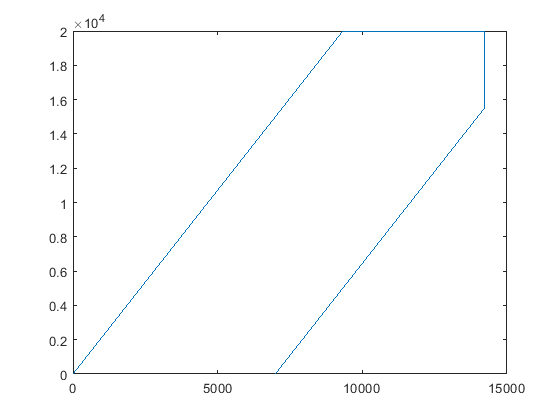

% чтоб изменить высоту антены нужно зименить размер l1
% l1 = ((h - 4457)/tand(angle) + b)/cosd(angle)*15/16; 


x_point_1 = 0;
y_point_1 = 0;

x_point_2 = l1*cosd(angle);
y_point_2 = l1*sind(angle);

y_point_4 = h - 4457;
x_point_4 = y_point_4/tand(angle) + b;

y_point_3 = y_point_2;
x_point_3 = x_point_4;

x_point_5 = b;
y_point_5 = 0;

X_point = horzcat(x_point_1, x_point_2, x_point_3, x_point_4, x_point_5);
Y_point = horzcat(y_point_1, y_point_2, y_point_3, y_point_4, y_point_5);

plot(X_point, Y_point)

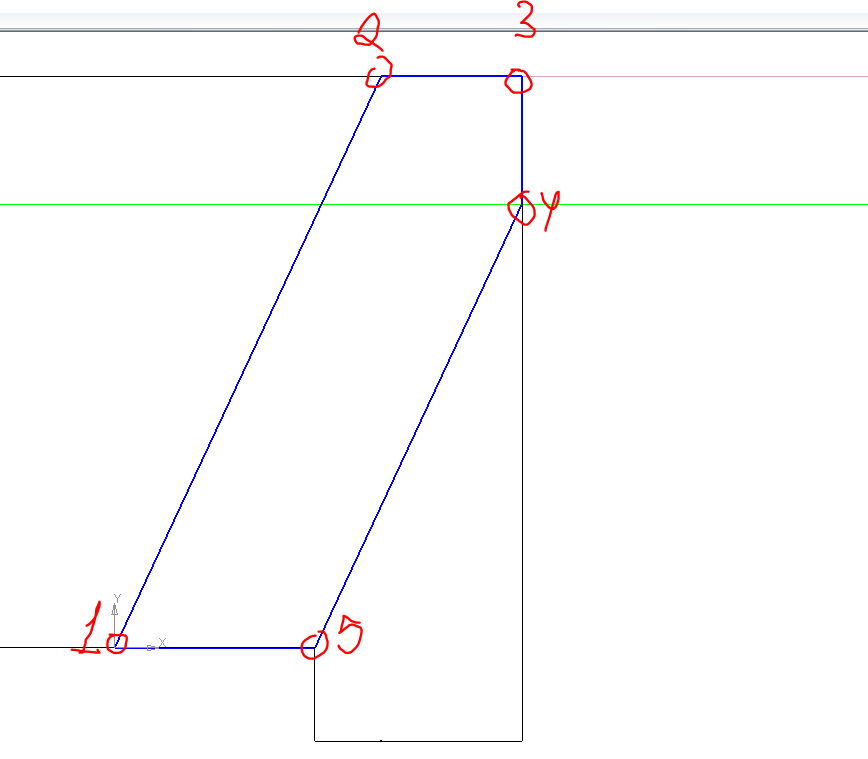

#### 3. Построение границ отрезков

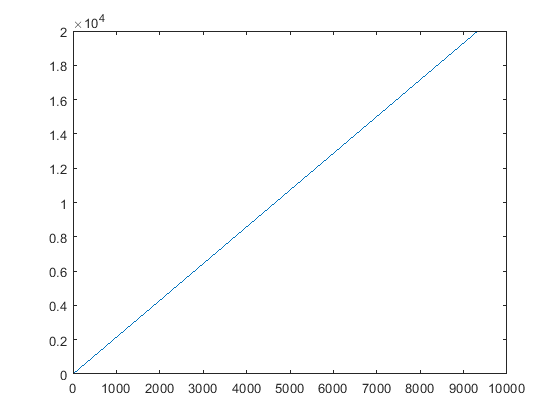

%% УЧАСТОК_1 - наклонный участок

% расчет шага 
l12 = l1;
% N12 = 100; % количество точек не участке 1
% dx_12 = l12/N12;
N12 =  round(l12*0.01,-1);
dx_12 = l12/N12;

% заполнение масивов
for i = 1 : N12
    step12 = dx_12*i;
    x1(i) = cosd(angle)*step12;
    y1(i) = sind(angle)*step12;
end


% график
plot(x1, y1)

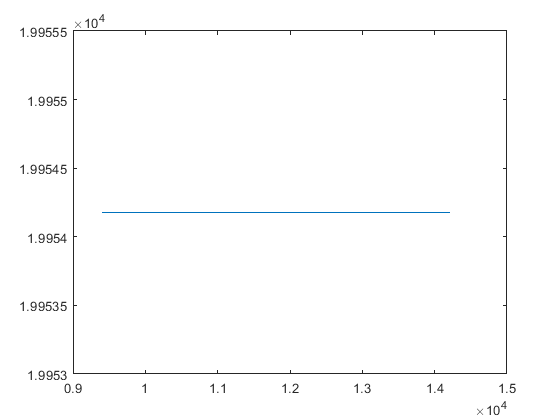

% УЧАСТОК 2 - горизонтальный участок

% расчет шага 
l23 = sqrt((x_point_2 - x_point_3)^2 + (y_point_2 - y_point_3)^2);
% N23 = 100;
% dx_23 = l23/N23;
N23 =  round(l23*0.01,-1);
dx_23 = l23/N23;

% заполнение масивов
for i = 1 : N23
    step23 = dx_23*i;
    x2(i) = x_point_2 + step23;
    y2(i) = y_point_2;
end

% временная шутка для построения графика
if l23 < 10^(-6)
    x2 = x_point_3;
    y2 = y_point_3
end
plot(x2, y2)

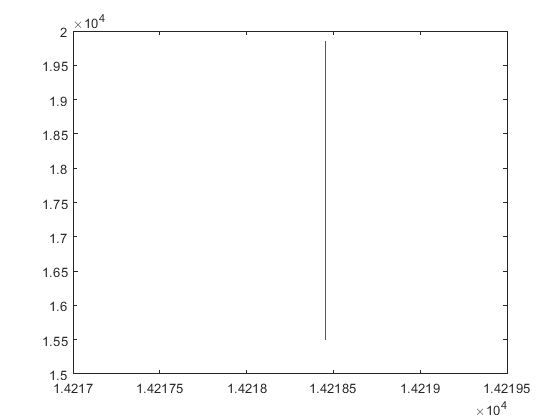

% УЧАСТОК 3 - вниз

% расчет шага 
l34 = sqrt((x_point_4 - x_point_3)^2 + (y_point_4 - y_point_3)^2);
% N34 = 100;
% dx_34 = l34/N34;
N34 =  round(l34*0.01,-1);
dx_34 = l34/N34;

for i = 1 : N34
    step34 = dx_34*i;
    x3(i) = x_point_3;
    y3(i) = y_point_3 - step34;
end

plot(x3, y3);

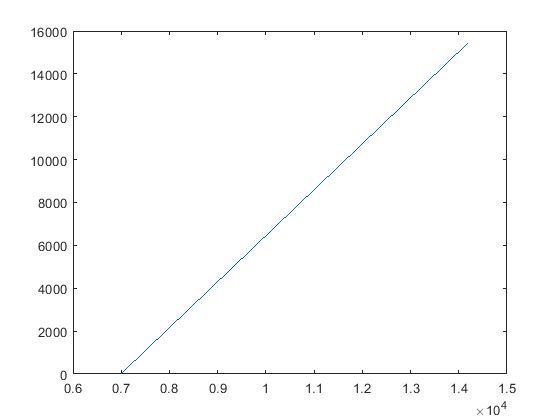

% УЧАСТОК 4 - наклон вниз
l45 = sqrt((x_point_5 - x_point_4)^2 + (y_point_5 - y_point_4)^2);
% N45 = 100;
% dx_45 = l45/N45;
N45 =  round(l45*0.01,-1);
dx_45 = l45/N45;

for i = 1 : N45 
    step45 = dx_45*i;
    x4(i) = x_point_4 - step45*cosd(angle);
    y4(i) = y_point_4 - step45*sind(angle);
end

plot(x4, y4);

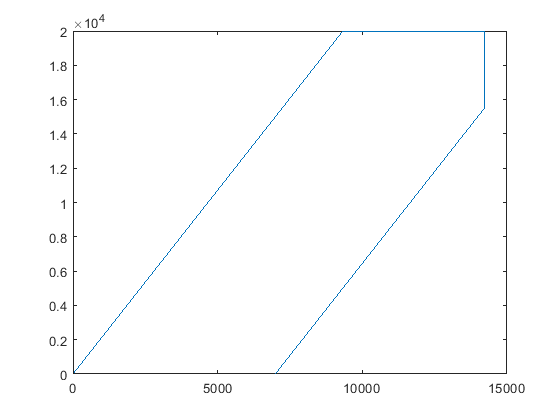

% cклеим все вместе 
X = horzcat(x1,x2,x3,x4);
Y = horzcat(y1,y2,y3,y4);
plot(X,Y)

Вторая часть антенны (под землей)

xi_point_1 = x_point_1;
yi_point_1 = -y_point_1;

xi_point_2 = x_point_2;
yi_point_2 = -y_point_2;

xi_point_3 = x_point_3;
yi_point_3 = -y_point_3;

xi_point_4 = x_point_4;
yi_point_4 = -y_point_4;

xi_point_5 = x_point_5;
yi_point_5 = -y_point_5;

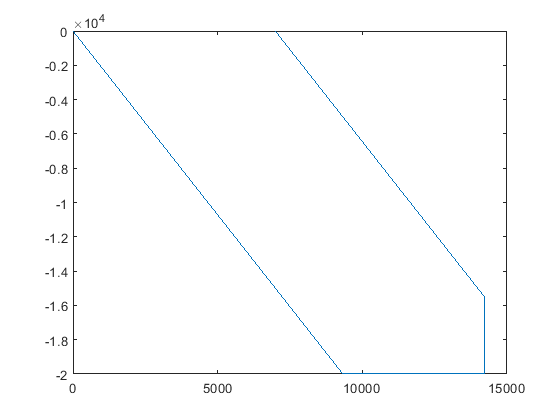

Xi_point = horzcat(xi_point_1, xi_point_2, xi_point_3, xi_point_4, xi_point_5);
Yi_point = horzcat(yi_point_1, yi_point_2, yi_point_3, yi_point_4, yi_point_5);

plot(Xi_point, Yi_point)

% %% УЧАСТОК_1 - наклонный участок
% % заполнение масивов
% for i = 1 : N12
%     step12 = dx_12*i-dx_12/2;
%     xi1(i) = xi_point_2 - cosd(angle)*step12;
%     yi1(i) = yi_point_2 - sind(angle)*step12;
% end
% 
% 
% % график
% plot(x1, y1)

% % УЧАСТОК 2 - горизонтальный участок
% % заполнение масивов
% for i = 1 : N23
%     step23 = dx_23*i-dx_23/2;
%     xi2(i) = xi_point_3 - step23;
%     yi2(i) = yi_point_3;
% end
% 
% % % временная шутка для построения графика
% % if l23 < 10^(-6)
% %     xi2 = xi_point_3;
% %     yi2 = yi_point_3
% % end
% plot(xi2, yi2)

% % УЧАСТОК 3 - вниз
% for i = 1 : N34
%     step34 = dx_34*i-dx_34/2;
%     xi3(i) = xi_point_4;
%     yi3(i) = yi_point_4 - step34;
% end
% 
% plot(xi3, yi3);

% % УЧАСТОК 4 - наклон вниз
% for i = 1 : N45
%     step45 = dx_45*i-dx_45/2;
%     xi4(i) = xi_point_5 + step45*cosd(angle);
%     yi4(i) = yi_point_5 - step45*sind(angle);
% end
% 
% plot(xi4, yi4);

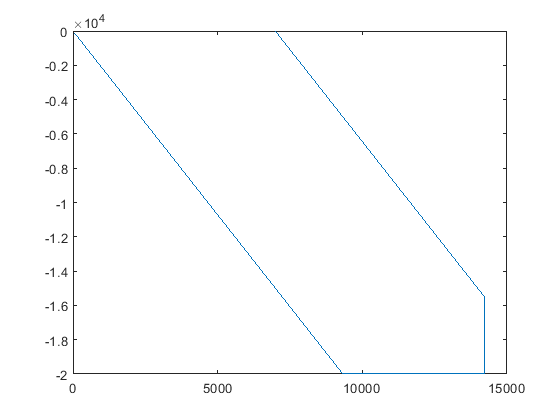

% cклеим все вместе 
Xi = flip(horzcat(x1,x2,x3,x4));
Yi = flip(horzcat(-y1,-y2,-y3,-y4));
plot(Xi,Yi)

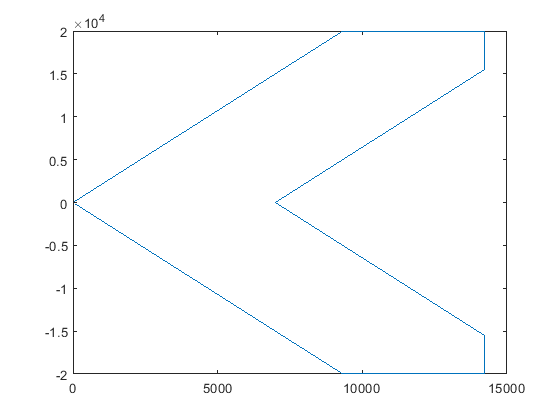

plot([X,Xi],[Y,Yi])